# Validación Controlador

addpath("controllers/PID/sims/")
addpath("controllers/PID/data/")
load("controllers/PID/data/TF.mat");
%load("controllers/PID/dat/PIDExp.mat");
addpath("resultados-finos/")
mat = readtable("resultados-finos/pid-red.xlsx"); 


% Lectura de los datos 
time = table2array(mat(:, 1));   % Tiempo
ref = table2array(mat(:, 2));    % Referencia de control
theta = table2array(mat(:, 3));  % lectura del sensor 
u = table2array(mat(:, 4));      % Accion de control 

time(end)

ans = 64.5475

simout = sim("controllers/PID/sims/plantaClosedLoopPID.slx", 60); % simluacion no lineal 
%load("dataExperimental-pid.mat");

t = simout.tout; 
y_nl = simout.nl_response.Data;
uSim = simout.uSim.Data;
timeU = linspace(0,time(end),length(uSim))

timeU =          0    0.0027    0.0054    0.0081    0.0108    0.0134    0.0161    0.0188    0.0215    0.0242    0.0269    0.0296    0.0323    0.0350    0.0377    0.0403    0.0430    0.0457    0.0484    0.0511    0.0538    0.0565    0.0592    0.0619    0.0645    0.0672    0.0699    0.0726    0.0753    0.0780    0.0807    0.0834    0.0861    0.0888    0.0914    0.0941    0.0968    0.0995    0.1022    0.1049    0.1076    0.1103    0.1130    0.1156    0.1183    0.1210    0.1237    0.1264    0.1291    0.1318


u = lowpass(u,100,1/2.5e-3)

u =    14.6586
   29.9158
   34.7417
   30.0011
   27.2028
   30.1422
   31.9913
   29.7513
   28.4813
   30.3441


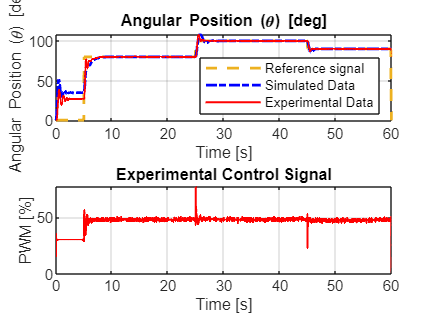


figure()
subplot(2,1,1)
plot(time, ref,"Color", "#EDB120","LineStyle",'--',"LineWidth",1.5);
hold on
plot(t,y_nl,"b-.","LineWidth",1.5);
plot(time,theta,"r","LineWidth",1);
grid on
title('Angular Position (\theta) [deg]')
xlabel('Time [s]')
ylabel('Angular Position (\theta) [deg]')
xlim([0 60])
legend('Reference signal','Simulated Data','Experimental Data','Location','southeast')
subplot(2,1,2)
plot(time,u,'r',"LineWidth",1);
grid on
title('Experimental Control Signal')
xlabel('Time [s]')
ylabel('PWM [%]')
xlim([0 60])